# Graphics & Data Visualization

## 1. Figure & Axis Basics

### 1.1 The Figure Window

All graphical output will end up in a so-called figure window. You can open new figure windows by typing `figure` on the command line. Plot commands typically show their results in the current figure window; a window becomes 'current' when you click in it, or when you bring it to the foreground of your desktop. 

Each figure window is numbered (shown in the title bar), and you can bring a specific figure (e.g. 1) to the foreground with `figure(1) `and you can request the number of the current figure by typing `gcf`(get current figure). If your analysis requires you to produce output in multiple figure windows, remembering those figure numbers can become a chore. 

Each figure window can contain one or more axes and each axis can contain one or more graphical objects (e.g. lines, images, markers, labels, titles). The simplest way to create a new axis is by simply executing a graphic command; Matlab will automatically generate an axis that fits within the (current) figure window.

#### 1.1.1 `subplot` and `tiledlayout`

You get more flexibility within the figure window by creating multiple sub-axes using either `subplot` or `tiledlayout`. The individual axes created using either of these functions are numbered going from left to right. For instance, for a figure with 3x3 different axes the axis numbers would be as follows:

axisNumbers = [1 2 3; 4 5 6; 7 8 9]

axisNumbers =      1     2     3
     4     5     6
     7     8     9


This is useful to remember if you are making multiple plots in a loop.

#### **1.1.2**` subplot`

This command creates a multi-panel figure with a specified number of rows and columns (`subplot(rows,columns,position)`). For instance, to generate a figure with panels in 2 rows and 3 columns, you type `subplot(2,3,1)`. This command creates an axis in the first position (top-left) of the six axes, `subplot(2,3,3)`creates an axis in the top-right position, and  `subplot(2,3,4)`, `subplot(2,3,5)`, `subplot(2,3,6)`fill in the bottom row of panels. Note that axes can also span two or more positions in a layout. For instance, `subplot(2,3,[4 5])`generates a subplot spanning the left and center position of the bottom row. 

If a figure has more than one axis, graphical commands will show their results in the current axis. To change which of your axes is the current one, you can retype the relevant subplot command. In other words, if subplot 3 already exists, then `subplot(2,2,3)` will not create another axis, but instead make that axis the current axis for all subsequent graphical commands.  

An example layout. Note how each of the graphical commands (e.g. `title`) is routed to the active axis. 

figure(1);
subplot(2,3,[1 4])
title('Left')
subplot(2,3,2);
title('Top Middle')
subplot(2,3,3);
title('Top Right')
subplot(2,3,[5 6]);title('Bottom Right')                            

The `subplot `command is particularly useful when you are analyzing data and want a simple, regular layout that just gets the job done. But its limitations become clear in more complex layout like the one shown above. For instance, a label added to the y-axis of the bottom-right panel would overlap with the left panel. You can fix such layout problems using the `axis` command, which gives you complete control over where the axis will be placed in the figure. More generally, you can manipulate axis properties (among many other things) via the handle interface (below). 

#### **1.1.3**` tiledlayout`

In 2020, Maltab introduced another way to create multiple axes within a figure, `tiledlayout`. The functionality is largely similar to `subplot`. However, the syntax is a bit different. It begins by calling `tiledlayout `with the numbers of rows and columns. Unlike `subplot`, the `tiledlayout` function creates the whole figure, as opposed to a specific axis. In order to create a specific axis (or 'tile'), call the `nexttile` function. Similar to the `figure `function, calling `nexttile` with no input arguments will create the next tile  (e.g., the first call will create the first axis, the second call will create the second axis, etc.). Alternatively, you can specify the position of the tile that you want to populate (e.g., `nexttile(3) `creates axes in tile 3). Another difference between `subplot` and `tilelayout `is the syntax needed to draw axes that span multiple tiles. For `tiledlayout` the `nextile `function is called with the tile number where the new axis will begin  (starting from the top left) followed by the number of rows and columns that the tile will populate (e.g., in a 2x3 layout `nexttile(5,[1 2])` corresponds to `subplot(2,3,[5 6])`). Putting this together, we can recreate the layout in the `subplot` section.

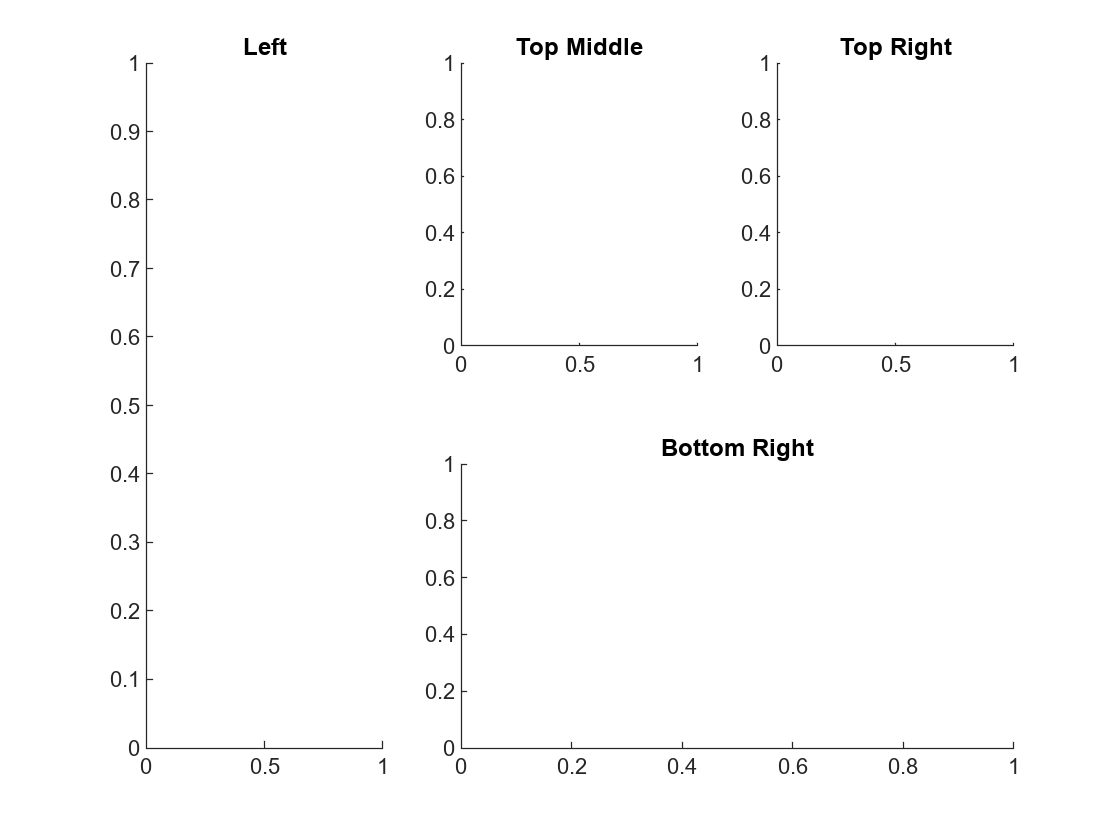

figure(2);
tiledlayout(2,3); 
nexttile(1,[2 1]); % creates left pannel
title('Left');
nexttile(2) % top-middle tile
title('Top Middle');
nexttile(3) % top right tile
title('Top Right');
nexttile(5,[1 2]) % bottom right panel
title('Bottom Right');

Two benefits to using `tiledlayout/nexttile` over subplot. First, TiledChartObject  allows you to pad all of the tiles in a single call, as opposed to positioning each subplot individual. The second is that it allows you to link axes, which is nice if, for isntance,  you have multiple plots that share an axis label. However, these objects are very new and most existing code you see will use subplot.

### 1.2 Figure and Axis Manipulation

There are two general ways to manipulate figure and axis properties: standalone graphical commands (e.g., `title`), handle manipulation (`set/get`, and dot-notation). 

#### 1.2.1 Standalone graphical commands

If you are creating a figure with a single set of axes, standalone graphical commands are a simple way to modify your figure/axes. Below is an example using some of the most common functions. Others will be used in later examples. 

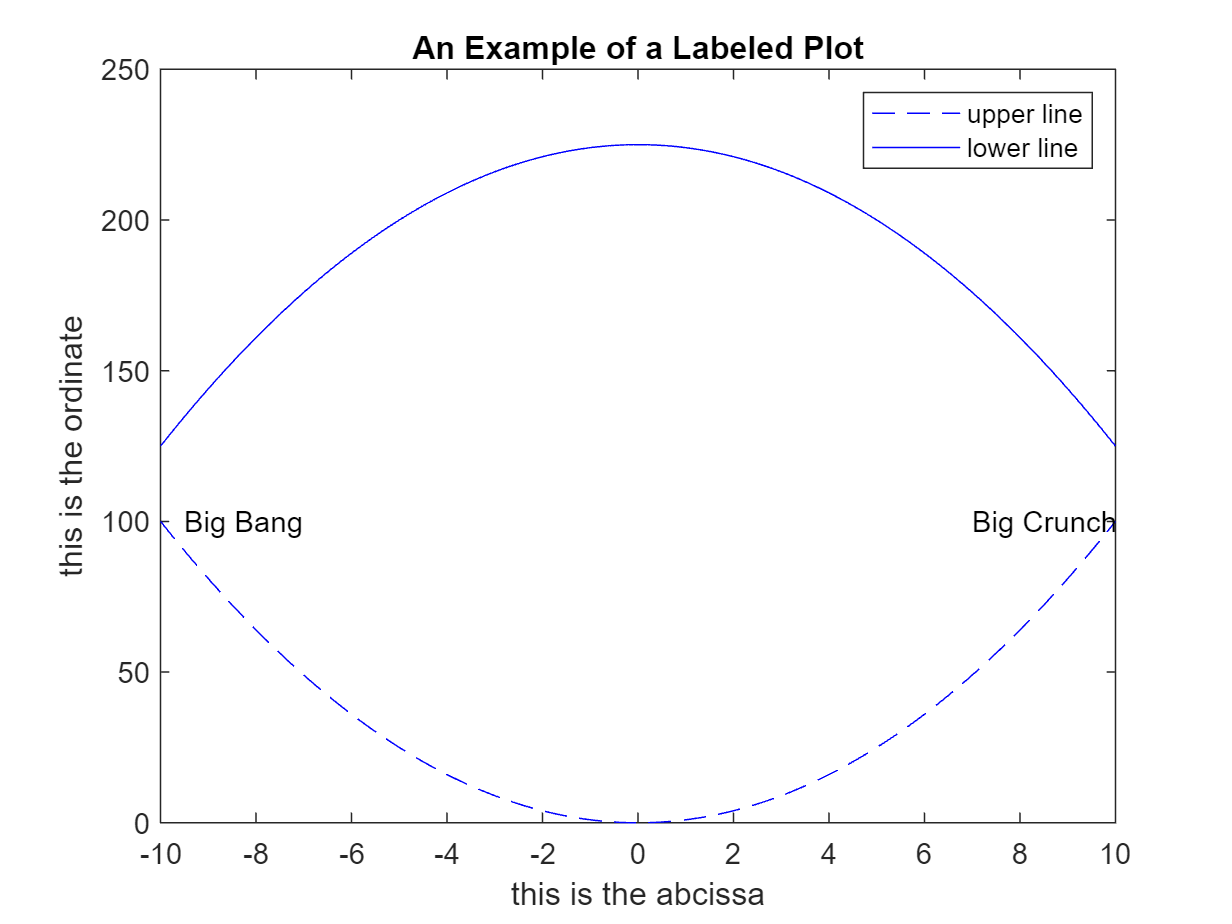

% generate some data
x = -10:0.1:10;
y = x.^2;

% create new figure window and plot some lines
figure(3)
clf% clear figure
plot(x,y,'b--'); % plot lower line
hold on % stay on the current axis(otherwise it will be overwritten by the next "plot" command
plot(x,225-y,'b-');% plot upper line
xlabel('this is the abcissa') % label x-axis
ylabel('this is the ordinate') % label y-axis
title('An Example of a Labeled Plot') % title
text(-9.5,100,'Big Bang') % add text on the left
text(7,100,'Big Crunch') % add text on the right
legend({'upper line','lower line'}) % add legend
xticks(-10:2:10) % add tick marks every two units on the x-axis

#### 1.2.2 Handle Manipulation

The functions described in the previous sections are the user-friendly interfaces to the underlying graphics elements. The functions are quite flexible and allow for a lot of fine-tuning. Read the `help` for each of these commands to find out how you can make graphs to suit your purpose. 

If, or rather when, the built-in functions are no longer powerful enough, when you want to move that legend just a bit to the left or give that title a slightly larger font, it is time to learn about handle graphics. 

Every object in a figure has a *handle*. The handle is an object that Matlab uses to keep track of all the dots, lines, axes, grids, legends etc that are currently on a figure. The simplest way to obtain a handle to a graphics object is to collect it from one of the standard function calls. The `plot `function, for instance, returns the handle of the line it plots, but other functions return multiple handles (e.g. to each of the bars in a histogram (`histogram`)). 

There are many ways to get the handle to a graphics object.

- Capture the return argument from the function that generates it (e.g. `h=plot(x,y)`). 

- Click on an object in a figure, and then ask Matlab for a handle to the current object with `h= gco`, the current axis (`gca`), or the current figure (`gcf`)

- Objects are organized in a parent/child hierarchy: all axes are children of a figure, and all graphical objects (lines, points, etc.) are children of axes. If you have a handle to a figure (from the `fig=gcf`, or `fig=figure`command), you can get all its axes by `axHandles = get(fig,'Children')`, and then `objHandles = get(axHandles,'Children')`. Conversely, if you have the handle to a graphical object, you can get its parent axis from `ax = get(h,'Parent')`.  This hierarchy is particularly useful to make sure that some properties of objects are the same across the all objects in the figure. For instance, the font of axis labels, legends, etc.Note that you can also set the properties of many objects at the same time. For instance if you have the handles to all lines in the vector `h`, `set(h,'LineWidth',2)` will set the linewidth for each of the lines. This too is a very useful way to ensure consistency in your graphics. 

- You can search for objects with the `findobj` function. This function returns the handle of all objects whose specified property has a specific value. For instance: `findobj('linestyle',':')`returns all objects whose `'linestyle'`property equals '`:`'. If there is no such object, the empty list is returned. By default, `findobj`starts looking for graphical objects from the root level. This means that all figures currently open in Matlab will be searched. To restrict the search to a particular figure, you can specify this figure's handle to the `findobj `function.  I.e. `findobj(figHandle,'color','r')`finds all red objects in the figure with the handle `figHandle`. You can be even more specific in your search by using multiple property/value pairs in a single call to `findobj`. For instance, `findobj(figHandle,'Color','r','type','line')`will return only handles to red lines, not red axes, or bar graphs. A special property, much used in combination with the `findobj `function, is the `'tag'` property. Matlab does not use this property internally, and it provides you with the possibility to tag a certain object with a name, and then later find this object again. I use this, for instance, to create a convenient way to refer to figures by name. Note that the `findobj` function can also look for a match of two property-value pairs. `h =findobj('tag','averaged','type','figure')`. This way I can be sure that the handle will refer to a figure (there could have been an axis with the tag `'averaged', `but this call to findobj will not return that axis’ handle).

The best way to learn about all the properties of an object is to simply type the variable that stores the handle on the command line (h) this will list all properties and their values in the object `h`. 

*An even more useful call is *`set(h)`* which not only shows you the property but also gives you information on the values that are allowed for each property. *

You can learn a lot from this list: it tells you which properties can be changed; hence it tells you how you can manipulate your graphics. To set the property of an object with handle `h` to a certain value, use the `set`command: `set(h,property,value)`, or use the notation `h.property = value;` Let's look at a few examples. 

figure(4)
x=-10:10;
y= 5+x.^2+x.^3;
h=plot(x,y)       

h =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-10 -9 -8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7 8 9 10]
              YData: [-895 -643 -443 -289 -175 -95 -43 -13 1 5 5 7 17 41 85 155 257 397 581 815 1105]

  Show all properties


The plot function returned a handle `h.` Some of its properties are shown on the command line, and you can get a complete listing of all properties by clicking on the ‘all properties’ link. 

The list of properties gives some information that is immediately meaningful (`'Linestyle','Linewidth','Color'`) while other properties are more cryptic (`'Clipping','Hittest'`), some of the latter are useful in interactive graphics and graphical user interfaces, so we'll skip them here. Note the `'XData'` and `'YData'`: these contain the actual data values that make up this line. This means that if you have a saved figure but no longer have access to the original data, you can retrieve them from the figure.

Let's use the set command to change some of the line object's properties:

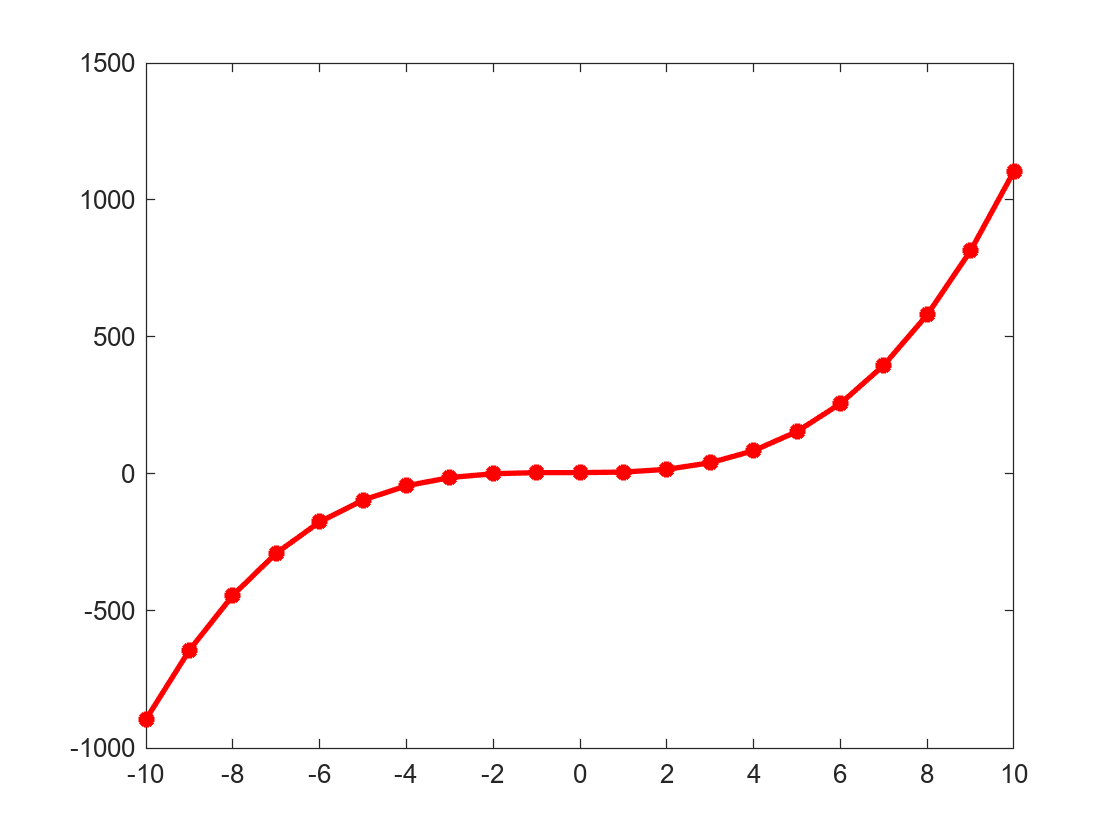

set(h,'Color','r') 
set(h,'LineWidth',2,'Marker','*')

Note how properties can be `set` one at a time (as in the first line of code) or multiple in one call to `set`.   

The same result could also be achieved with the dot-noation:

h.Color = 'r';
h.LineWidth = 2;
h.Marker = '*';

Not all values are legal values for every property. For instance, you cannot set the 'Marker' property to 'q' or to 2. To find out the legal values for a property, use the set command without specifying a value:

set(h,'Marker')  

  16×1 cell array

    {'+'        }
    {'o'        }
    {'*'        }
    {'.'        }
    {'x'        }
    {'square'   }
    {'diamond'  }
    {'v'        }
    {'^'        }
    {'>'        }
    {'<'        }
    {'pentagram'}
    {'hexagram' }
    {'|'        }
    {'_'        }
    {'none'     }



Many of the property/value pairs that you can modifiy with `set` can also be specified in the call to the graphics commands. So instead of returning a handle, and then using the handle to set the properties, you can combine these commands into one line:

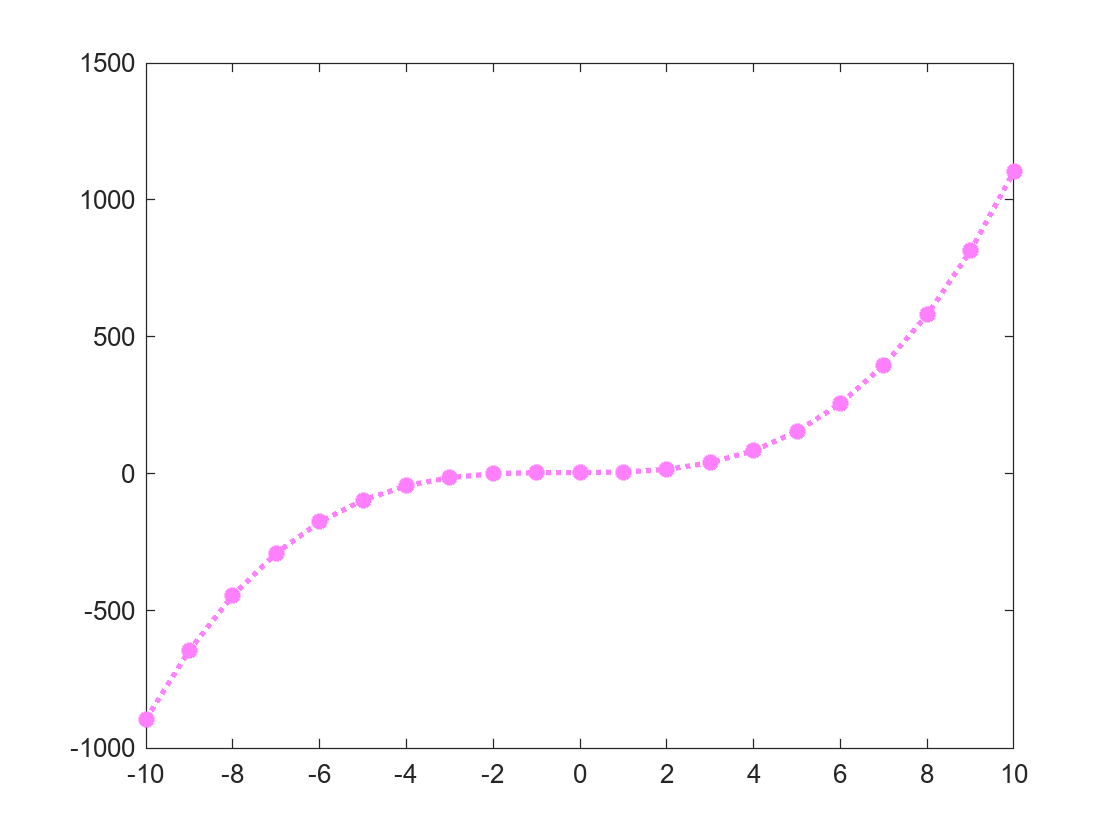

figure(5) 
plot(x,y,'Color',[1 0.5 1],'Linestyle',':','LineWidth',2,'Marker','*')  

Note that I used a numeric triplet to specify the color puple. This three-vector specifies the mixing proportions of red, blue, and green light: [1 1 1] is white, [1 0 0] red and [1 1 0] an even mixture of red and green (i.e. yellow). This is useful when the standard colors of the plot function are not distinct enough.

Finally, another way to set the properties of handle objects is to use a `struct`:

`props.Color = [1 0.5 1];`

`props.Linestyle = ':';`

`props.LineWidth = 2;`

`props.Marker = '*';`

`set(h,props)`

This makes code much more readable and reusable, as you can also use this to extract the properties of one object, change one of them, and apply it to another:

`props = get(h);`

`props.Color = 'g';`

`set(h2,props)`

## 2. Data Visualization

The previous sections have covered some of the basic properties of figures and axes as well as how to manipulate them. The following sections will provide examples of some of the most common types of graphics used in Neuroscience, including those used for both behavioral and neural data.  

### 2.1 Line graphs and errorbars

#### 2.1.1 `plot`

The most basic graphical command is `'plot`'. In its simplest form it simply draws a line between the values that you supply. For instance if we have a vector with mean behavioral performance across different experimental conditions. 

***Quick Primer on 2-Alternative Forced-Choice Tasks ***

In short, 2-Alternative Forced-Choice (2AFC) paradigms require subjects  to make one of two responses to some stimulus/set of stimuli. This type of task is used to probe a variety of different behaviors including sensory discrimination, attention, and valuation. A benefit to 2AFCs is that their simplicity and flexibility make them well suited to both human and animal models. The choice data used in the following example comes from a value-based 2AFC task in which subjects were required to choose between one of two stimuli, each with their own value. The conditions are defined as the difference between the value of the item on the left minus the value of the item on the right. Performance is assessed as the probability of choosing the item on the left. Since the conditions are the difference between the left minus the right item, a negative value indicates that the item on the right was bigger (in which case we would expect a lower proportion of left choices) and a positive value indicates that the item on the left was larger (in which case we would expect a higher proportion of left choices). 

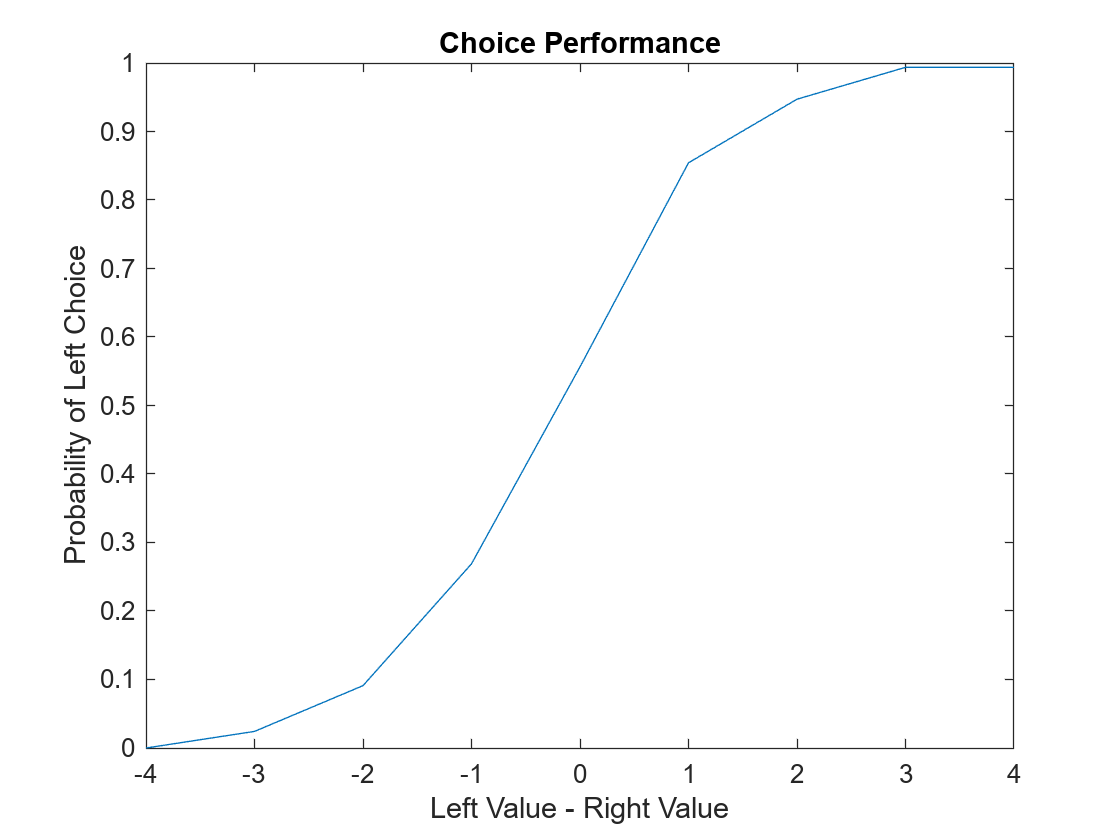

% clear variables and the command line
clear;clc

% load choice data
load ../data/choiceData 

% plot choice probabilities by condition
figure
plot(condition,choice)
title('Choice Performance') % add title
xlabel('Left Value - Right Value') % add label to x-axis
ylabel('Probability of Left Choice') % add label to y-axis

This graph gives a general sense of the subjects' behavioral performance. However, it is difficult to make out the values of the 9 data points without markers. Another helpful addition to this graph would be errorbars to help visualize the amount of variability across conditions. As described earlier, the `plot `function can take arguments about formatting including the addition of markers. However, since we wish to add errorbars as well, we will turn to the `errorbar` function.

#### 2.1.2 `errorbar`

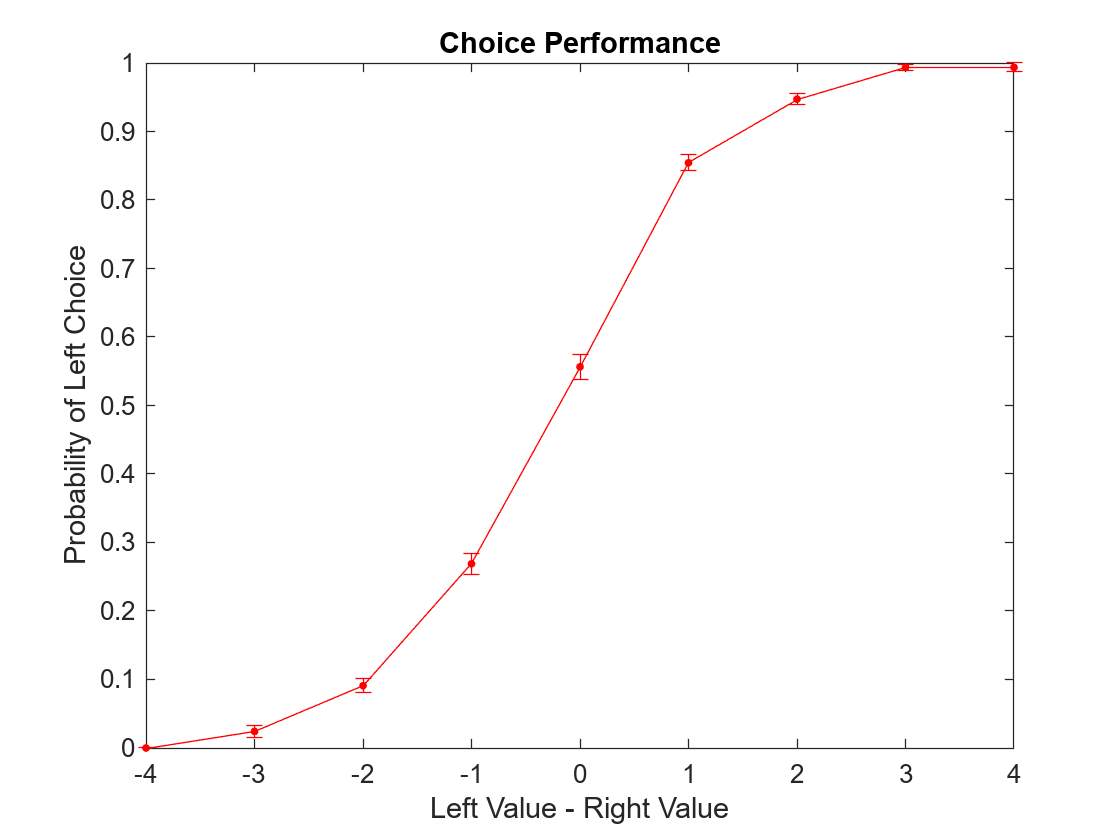

figure
errorbar(condition, choice, choice_sem,'r.-','markerSize',10); ylim([0 1]);
title('Choice Performance') % add title
xlabel('Left Value - Right Value') % add label to x-axis
ylabel('Probability of Left Choice') % add label to y-axis

As you can see, the call to `errorbar` took the same input as `plot`, but also includes the variable `choice_sem` which contains the standard error of the mean (sem) for each of the 9 measurements to be used to create the errorbars. Also included in the call was information about the color, size, and type of marker/line. The argument `'r.-' `tells the function to connect filled circular markers with a straight line and to make the marker, line, and errorbars red. The second argument `'markerSize'` sets the size of the markers (in this case to make them more visible). 

### 2.2 Bar graphs, why not to use them, and what to use instead

Bar charts are commonly used to show properties of different categories which have no clear numerical relation to each other (such as cells from monkey A vs B, subject A vs B etc.). As an example, consider a reaction time experiment. The data in the `rtData `mat file contains the data for 2 groups of 100 subjects.  First, lets' compare the average reaction times for the two groups. 

#### 2.2.1 `bar`

%house keeping
clear;clc

% load data
load ../data/rtData

% get the average reaction times for each subject
figure;
meanReactionTime = squeeze([mean(ctlRT) mean(exptRT)]);

% make the subject names a single categorical variable
groups = categorical({'control' 'experimental'});
bar(groups,meanReactionTime);

% add title and axis labels
title('Reaction Time Across Subjects')
xlabel('Group')
ylabel('reaction time (ms)')

 Let's add some errorbars to provide some more information. To do this, we will use the `hold` function, followed by a call to the `errorbar` function with the `'LineStyle'`argument set to `'none'`. 

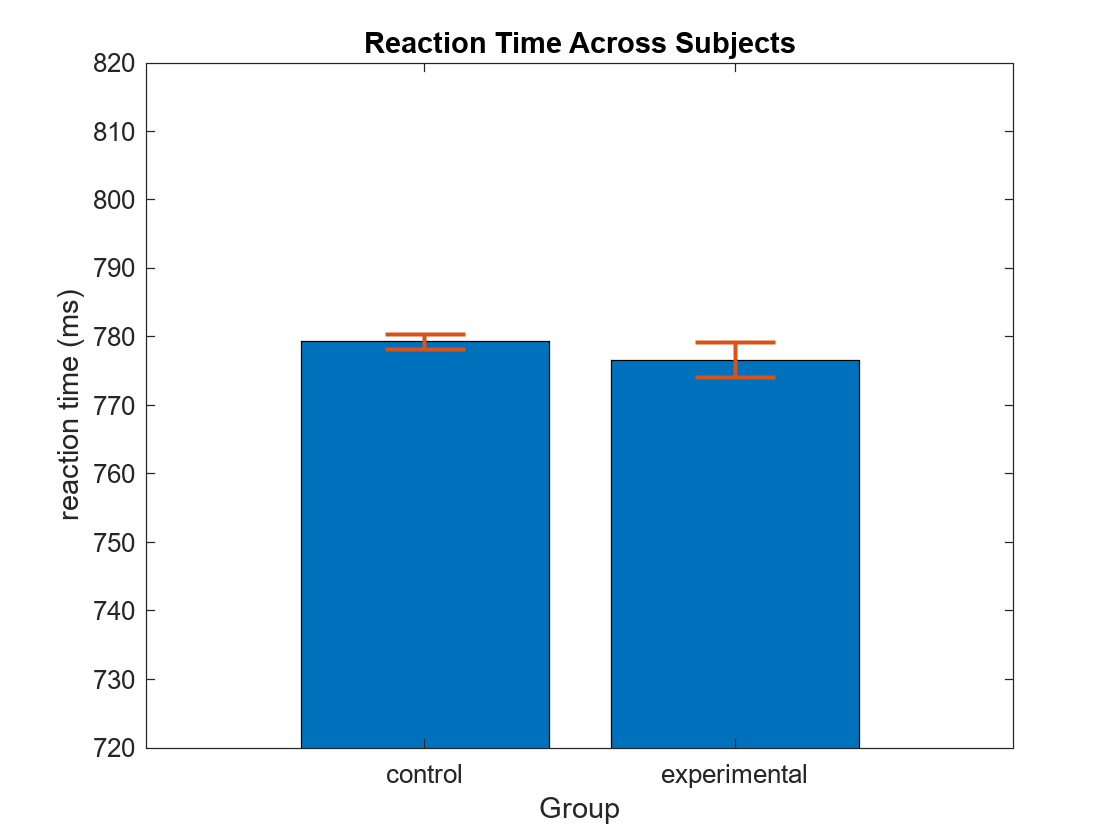

hold on
% add errorbars
nrSubjects = [numel(ctlRT) numel(exptRT)];
sem  = [std(ctlRT) std(exptRT)]./sqrt(nrSubjects); 
errorbar(meanReactionTime,sem,'LineStyle','none','linewidth',1.5,'CapSize',30); 
ylim([720 820]) % Truncate the y-axis to make the small errorbars more visible

#### 2.2.2 `histogram`

Looking at this graph it looks like there is no signficant difference between the groups. But in reality this graph just tells us that the *mean* is not different between the groups. Plotting the data in this manner, with just the mean and sem, is really only good if your data are normally distributed. Further, even if the data is normally distrubted, plotting a bar graph obscures information about the sample by reducing it to a single number (e.g., the mean). Let's look more closely at this dataset by plotting the histograms of the two groups. 

figure
nrBins = 10; 
fig = tiledlayout(1,2);
% plot the control group
axCtl2 = nexttile;  
hCtl = histogram(ctlRT,nrBins);
title('Control')
% plot the experimental group
axExp = nexttile;
hExp = histogram(exptRT,nrBins);
title('Experimental')

Let's tidy up the axes so that they are the same for both plots using the `linkaxes` command. Note how I used a variable prefix `ax `to store handles to the axes and a prefix `h` to store the handle to the histogram. Using such conventions for variable naming improves the readability of your code.

linkaxes([axCtl2 axExp],'xy'); % this will match the axes on the two tiles simultaneously
xlabel(fig,'Reaction Time (ms)') % add unifed x-axis label. Note that we are using the figure handle not the axis handles
ylabel(fig,'Frequency')

Here we chose to bin each datset into 10 equal bins. However, if we want more control, we could instead specify the bin edges `histogram(data,edges)`. To do this, the bin edges are a vector starting with the lower edge of the first bin to the upper edge of the last bin. For example, here  are the bin edges that matlab automatically generated for the two groups. 

edgeE = hExp.BinEdges

edgeE =    720   731   742   753   764   775   786   797   808   819   830


edgeC = hCtl.BinEdges

edgeC =   752.0000  756.9000  761.8000  766.7000  771.6000  776.5000  781.4000  786.3000  791.2000  796.1000  801.0000


Below is the same graph however the bins for the two groups are now identical, which makes the comparison between the plots simpler.  

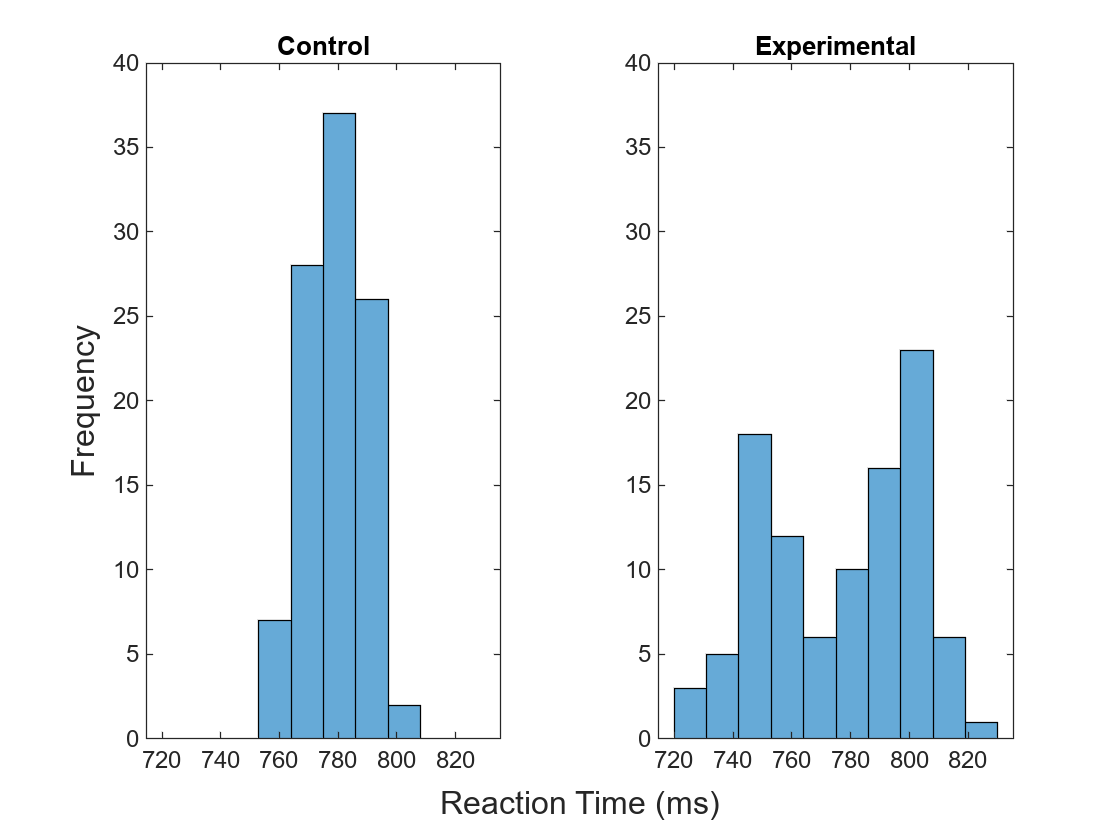

fig = tiledlayout(1,2);
% plot the control group
axCtl = nexttile;
hCtl = histogram(ctlRT,edgeE);
title('Control')
% plot the experimental group
axExp = nexttile;
hExp = histogram(exptRT,edgeE);
title('Experimental')

linkaxes([axCtl axExp],'xy'); % Match axes
xlabel(fig,'Reaction Time (ms)') % Add unifed x-axis label. 
ylabel(fig,'Frequency')

As a reminder, here is a look at the mean reaction times for the two groups. 

meanReactionTime

meanReactionTime =   779.2713  776.6398


As you can see, despite having very similar means, the distributions of each of the two groups are clearly different. Whereas the control group looks (fairly) normally distributed with a peak (mean) at around 780, the experimental group has a bimodal distribution with peaks at about 750 and 800. The question, then, is what type of plot is best for this type of data. 

#### 2.2.3 `boxplot`

One option is to use a box plot which will provide more information about the distributions such as the bounds of the 1st and 3rd quartiles, the median, and outliers. Here are  boxplots of the two distributions plotted on the same axes. 

In order to plot the two distributions on the same axes, we needed a dummy variable  that will indicate which rts belong to each group. 

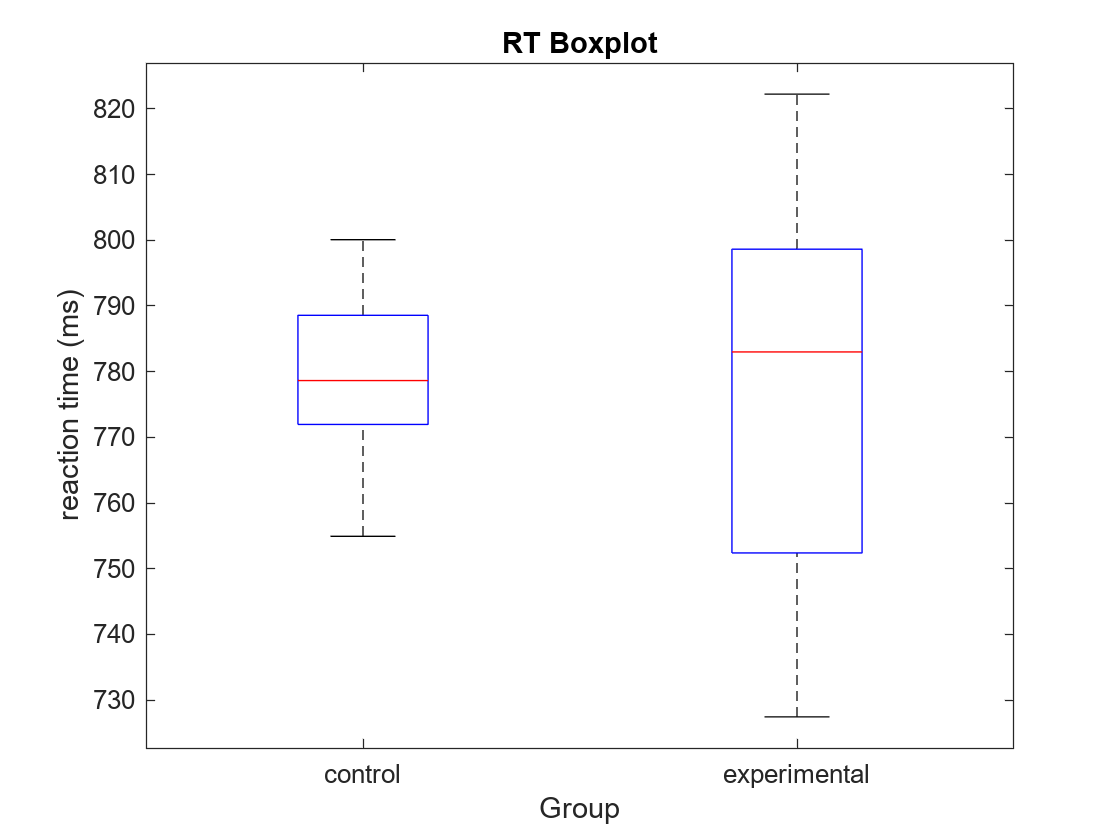

% create dummy grouping variable: zeros for the control subjects and ones
% for the experimental subjects
figure
grp = [zeros(1,nrSubjects(1)),ones(1,nrSubjects(2))];
boxplot([ctlRT exptRT],grp,'labels',string(groups));
title('RT Boxplot')
xlabel('Group')
ylabel('reaction time (ms)')

Unlike the bar graphs, the boxplots accurrately portrays the differntial widths of the two distribution. As shown in the histograms, the control group has a narrower distribution than the experimental group. However, the boxplot still does not capture the bimodality in the RTs of the experimental group. 

#### 2.2.4 Violin Plots

A violin plot is similar to a boxplot however the "box" ris eplaced with a smoothed probability density function that is estimated from the data. For a nice illustration on the benefits of violin plots over boxplots, see the gif below. As you can see, the boxplot remains static while the raw data shifts while the violin plot shifts along with the raw data.

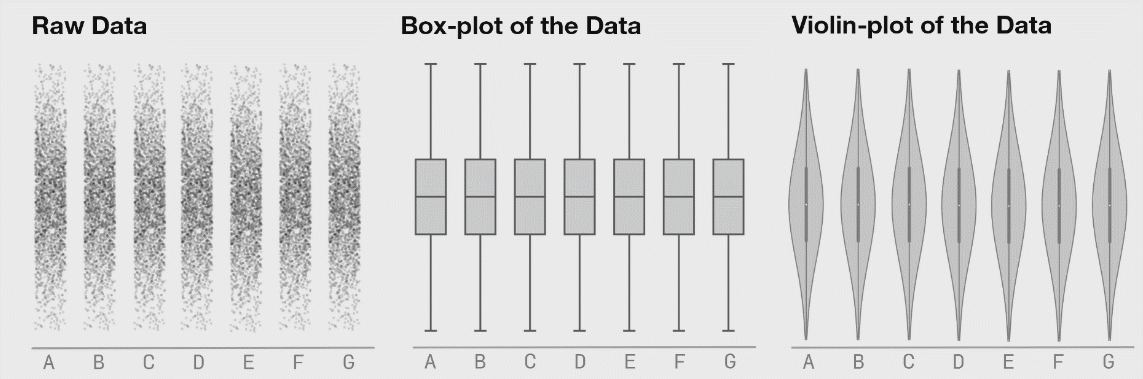

[source](https://www.autodeskresearch.com/publications/samestats)

**File Exchange**

Unfortunately, Matlab does not have a builtin function to create violin plots. However, there are many on the fileExchange*. Some examples include: `violin `and `distributionPlot`. Below is an example using `violin, which is `the most user friendly of the options on the File Exchange, so it is the one that will be used here ([(it is included in this repository)](matlab:open('..\code\violin.m')).. Others (and packages such as gramm) provide more options to play with, so I recommend checking them out. 

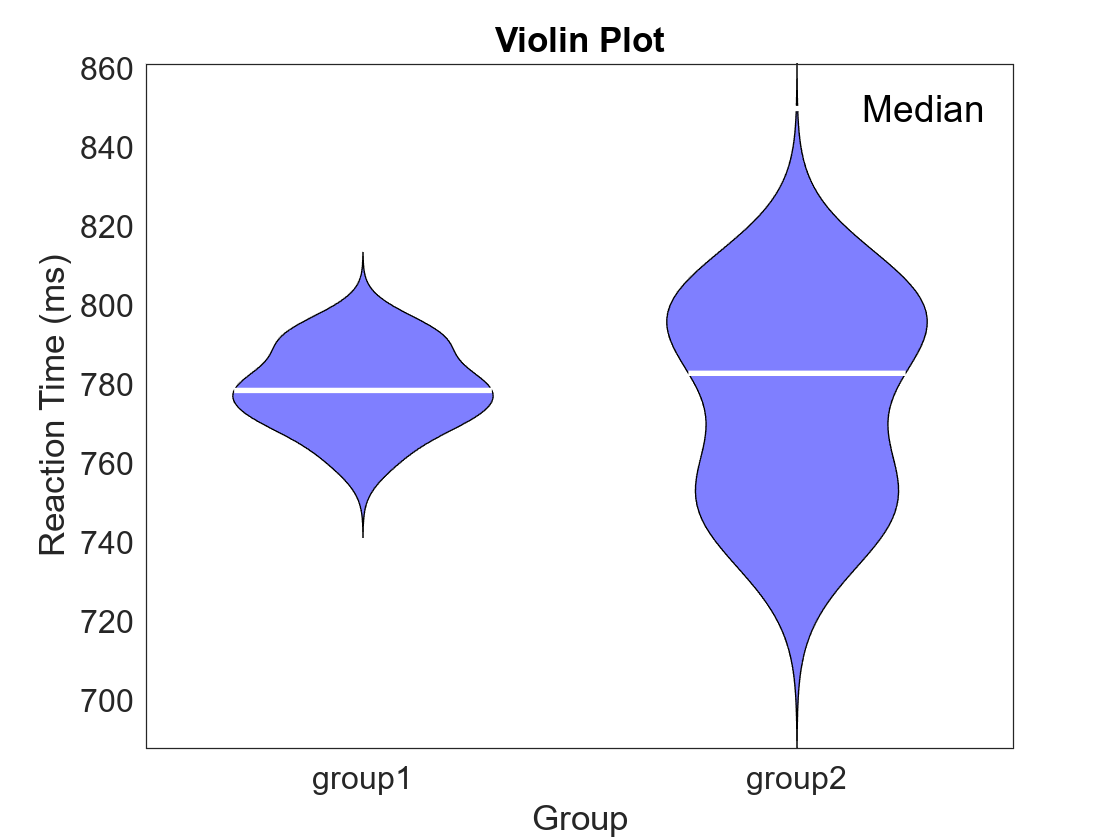

close
figure
violin([ctlRT exptRT],'xlabel',{'group1','group2'},'medc','white','mc',[],'plotLegend',0,'facecolor','b');% medc is the color for the median marker. mc is the color for the mean marker, which I have excluded here
xlabel('Group')
ylabel('Reaction Time (ms)')
title('Violin Plot')

***Never use file exchange functions blindly. Just like any other code, they may have bugs. Always inspect any functions that you download and make sure you know what they are doing. **

**gramm**

Another helpful toolbox is gramm ([https://github.com/piermorel/gramm](https://github.com/piermorel/gramm)), which was created based on the more extensive ggplot library in R. Here is an example of a violin plot with a boxplot superimposed for comparison. Check out the github link for more details including the accompanying publication.  **Please install the gramm toolbox before running this code!**

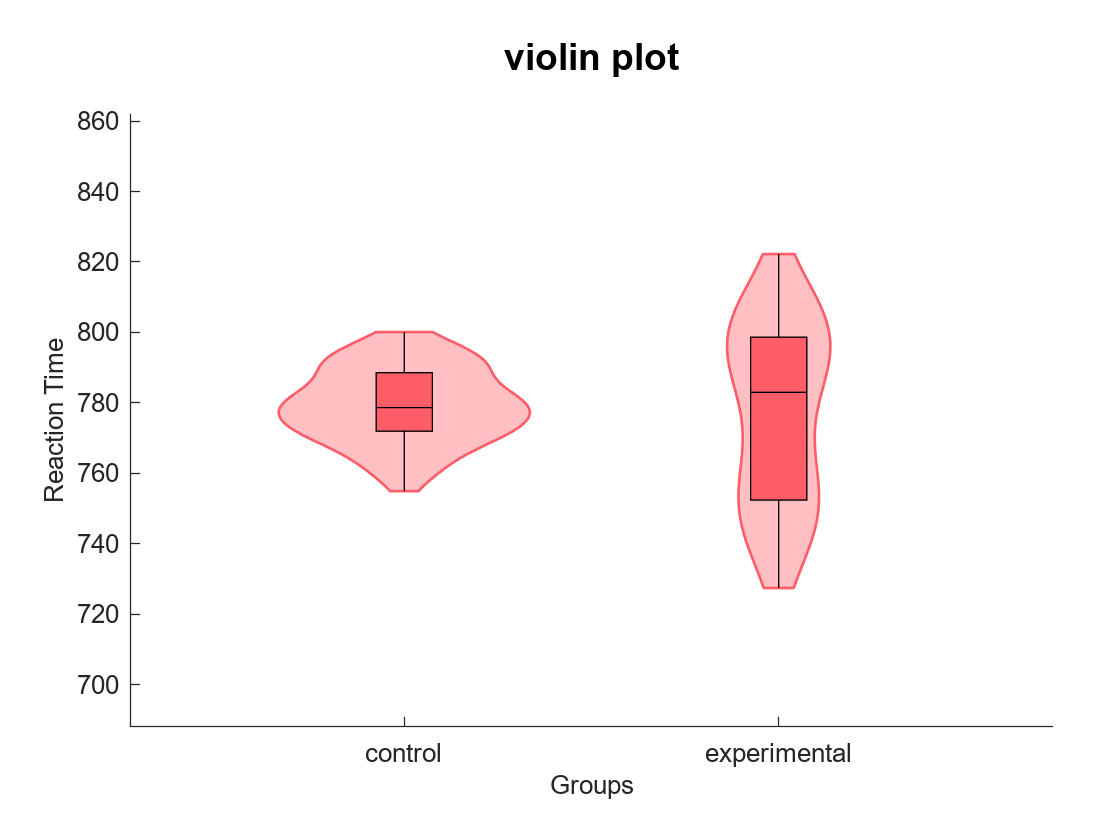

g = gramm('x',categorical(grp'),'y',[ctlRT;exptRT]);
g.set_names('x','Groups','y','Reaction Time');
g.stat_violin('fill','transparent');
g.stat_boxplot('width',0.15);
g.set_title('violin plot');
g.axe_property('XTickLabel',string(groups),'ylim',[688 862]);  %Crop for visibility
figure;
g.draw();

Note that the violin plots in the two figures are not identical, though they have roughly the same profile. This is because the two methods use different smoothing methods. For more information type `edit stat_violin` (lines 82-93) or `edit violin `(lines 162-166)to compare the functions. 

The botttom line is that, while bar plots have been popular, they should be used sparingly, IF EVER! 

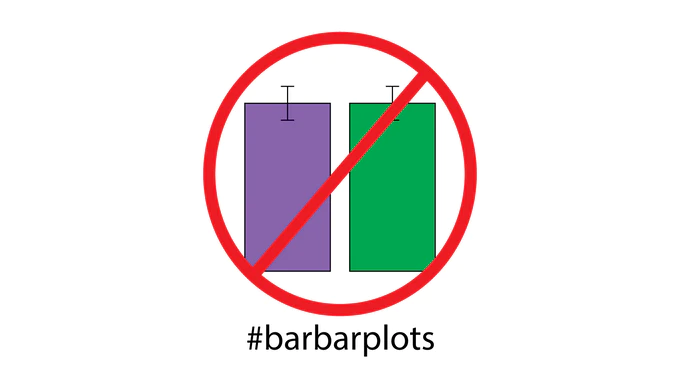

[source](https://www.kickstarter.com/projects/1474588473/barbarplots)

### 2.3 Raster Plots & Per-Stimulus Time Histograms (PSTHs)

#### 2.3.1 Raster Plots (`imagesc`)

Raster plots are a useful way to visualize spiking trains. They are often used to depict the spike trains of several neurons over a single trial or  a single neuron over multiple trials (though they can be used for other events, not just spiking events ).  The following example shows spike trains for a single neuron over 25 trials, each trial is 1500 milliseconds. A simple way to create a raster plot is to use `imagesc` which uses the values in a matrix to scale the colors of a `colormap.`  These maps tell Matlab how the numerical values in the matrix that you want to plot map onto colors. The matrix `spikes` contains a nrTrials x nrTimePoints matrix with 1s for the timepoints where a spike occured and 0 everywhere else. 

clear;clc

load ../data/spikeData
figure;
layoutSpk = tiledlayout(2,2);
axRaster = nexttile(1,[1 2]);
imagesc(spikes); hold on

Each row in the figure above is a trial and the x-axis represents time. Each tick mark in the graph represents a single spike. Since a specific colormap was not specified in this call to `imagesc` the figure above uses the default which results in a dark blue (all 0s) and yellow tick marks (1s). Let's change the colomap to a grayscale colormap using the `colormap` function with `gray` as the input argument. Unfortunately, the colormap maps 0 to black and 1 to white. In order to reverse this, use the `flipud `function to flip the colormap matrix in an up-to-down direction. 

colormap(flipud(gray))

Add some basic information to the plot. 

yticks(1:2:25)
ylabel('trial #')
xlabel('time (ms)')
xticks(0:200:1250)
ylim([0 nrTrials+1])
set(axRaster,'Box','off')

Add informative markers about events that took place during the trial. Here is some of the pertinent information. The following variables were defined in the data file:

stimStart % time that stimulus turned on

stimStart = 250

stimStop  % time that stimulus turned off

stimStop = 1000

latency % response latency

latency = 80

To start, we'll add a colored patch that illustrates the period of time during with the stimulus was on. The `patch` function draws a shape based on a set of x,y coordinates, indicating the vertices of the intended shape. 

% Create the x and y coordinates of the patch. Note how the x and y values
% go counter-clockwise around the patch, starting in top left corner.
patchX = [stimStart stimStart stimStop stimStop]';
patchY = [0 nrTrials+1 nrTrials+1 0]';


% Create the patch. 
patch(patchX,patchY,'g','FaceAlpha',0.1,'edgeColor','none'); % patch color is green, transparency at 0.1, no edges.
% Add a label over the top of the patch
text(500,-0.7,'Stimulus Duration')
hTitle = title('Raster');
% in order to place the title above the text placed over the stimulus duration patch, we need to change the y-value of the title 
hTitle.Position(2) = -1.1; % next change the value of the y-coordinate

Add a red line indicating the response latency using  `line` function. 

line([stimStart+latency stimStart+latency],[0 nrTrials+1],'Color','r','lineWidth',1.5);

Next, we can use the `annotation` function to add a text arrow pointing to and labeling this line. Unfortunately, the `annotation` function plots things in figure coordinates, not axis coordinates. As a result, we first need to convert the coordinates where we would like the arrow and text. To do this, we will use the ds2nfu function from the fileExchange ([also included in the repository](matlab:open('..\code\ds2nfu.m'))).  You will see that I am using `get` in order to find the y-coordinates. The reason for this is that it creates more flexible code--even if the y-axis limit changes, this code will still work. 

% convert data
[x2, ~] = ds2nfu(stimStart-3, max(get(gca,'YLim')));%start of arrow in the middle of the y-axis
[x3, y3] = ds2nfu(stimStart+latency,max(get(gca,'YLim'))/2); %tip of arrow
annotation('textarrow',[x2 x3],[y3 y3],'String',{'Response'; 'Latency'});

#### 2.3.2 PSTH with continuous errorbars (`plot` & `patch)`

Raster plots are a great way to visualize the data for single trials or cells. However, sometimes it is useful to also have a figure that summarizes this data. Peri-stimulus time histograms are frequently used to achieve this. In a general sense, a PSTH shows the spiking probability density function (pdf) over time. The basic steps to creating a PSTH are as follows, though there are several variants that exist:

- Break up trial duration into a specified number of bins separated by a specified timestep. The choice of bins and timestep (i.e., whether the bins overlap) will determine the amount of smoothing applied to your data. So choose carefully. 

- Count the number of spikes in each bin in each trial/cell

- Aggregate (sum/mean) the spikes in each bin over trials/cells

- Plot as a histogram with bars or as a line graph. If you took the mean of each bin, you can also add errorbars

% choose bin width (in ms)
binSize = 50;
% choose step size
step = 20; % since the step size is smaller than the bin size, this will create overlapping bins

% create bins 
centers = min(time):step:max(time);
centers = (centers(1:end-1) + step/2)';
bins = [centers - binSize/2, centers + binSize/2];
bins = mat2cell(bins, ones(length(centers),1));
nrBins = numel(bins);
cols = cell(1,nrTrials); % pre-allocate
counts = nan(nrTrials,nrBins);
for trial = 1:nrTrials
    % find the number of spikes in each bin for each trial
    [~, cols{trial}] = find(spikes(trial,:) == 1); % this will give the time point of the spikes since the vector is all 0s and 1s
     counts(trial,:) = cellfun(@(x) sum(cols{trial} > x(1) & cols{trial} <= x(2)), bins);
end

% sum/average the binned spike counts across trials
nrSpikes = sum(counts);
avgSpikes = mean(counts,"omitnan");
semSpikes = std(counts,0,1,"omitnan")./sqrt(nrSpikes);


Next, lets plot the data as a line graph with errorbars. However, instead of the classic errorbars let's use continuous errorbars surrounding the line. While there are several functions on the file exchange to create this type of errorbar (e.g., `shadedErrorBars, errorfill, `etc.), they all use the same basic technique--creating a patch around the line. Since this is pretty straightforward, I created my own simple function that outputs the x-y coordinates. For illustrative purposes, I have copied/commented out the function and re-typed included the "meat" of the function here. Since we are only creating one set of continuous errorbars, this is not anymore time consuming. 

% function [x_out, y_out] = continuousErrobars(centers,avgSpikes,semSpikes)
% x_out = [centers ; flipud(centers)]';
% y_bottoms = avgSpikes-semSpikes;
% y_tops = avgSpikes+semSpikes;
% y_out = [y_bottoms fliplr(y_tops)];
% end

xSem = [centers ; flipud(centers)]';
yBottoms = avgSpikes-semSpikes;
yTops = avgSpikes+semSpikes;
ySem = [yBottoms fliplr(yTops)];

Time to generate the plot!

% plot a simple line graph showing number of spieks over time (i.e., PSTH)
axPsth = nexttile(3,[1 2]);
plot(centers, avgSpikes,'k','linewidth',0.5); hold on
% add errorbars
patch(xSem,ySem,'r','FaceAlpha',0.25,'edgeColor','none');
title('PSTH')
ylabel('average # of spikes')
axPsth.Box = 'off';

Next, let's add the same markups that we added to the raster. 

ymax = max(get(gca,'YLim'));
stimDuration2 = [stimStart 0; stimStart ymax; stimStop ymax; stimStop 0];

lat = line((stimStart+latency)*[1 1],[0 ymax],'Color','r','lineWidth',1.5);
dur = patch(stimDuration2(:,1),stimDuration2(:,2),'g','FaceAlpha',0.1,'edgeColor','none');

% since we plotted out line first, it is now under the duration patch and
% the latency marker. To move these to these to the back, use the following
% command
uistack([lat dur],'bottom')

Lastly' let's format the x-axes so that they are identical to each other. To make this easier, let's first link the x-axes of the two tiles, since they are the same. 

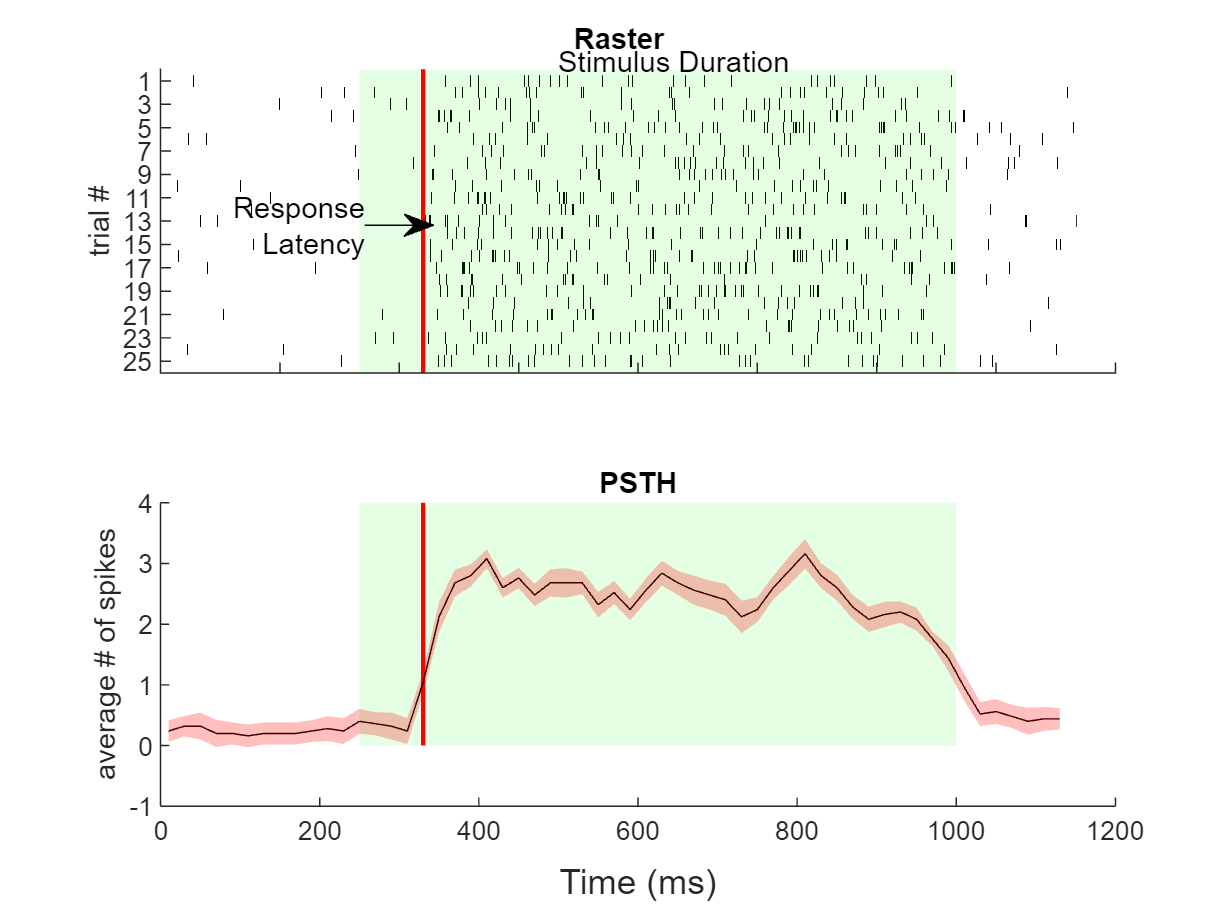

% first, let's get rid of the tick marks and label on the x-axis of te raster
axRaster.XTickLabel = [];
axRaster.XLabel = [];
linkaxes([axRaster, axPsth],'x')
xlabel(layoutSpk,'Time (ms)')
xlim(axRaster,[0 1200])
xticks(axRaster, 0:150:1200)